# Aula 11 - Laboratório de Controle - 2022/1

## Projeto do controlador avanço-atraso para o motor CC

## **Nomes:   **

Identificar porta serial do Arduino (Programa2_versao2.ino)

if ~exist('obj')
    z=seriallist;
    comPort=z{length(z)};
    obj=serial(comPort,'BaudRate',9600);
    obj.Terminator='CR';
    fopen(obj);
end


**Atividade 1: Obtenção do modelo do motor CC para um ponto de operação**

Ts=10;
Tempo=1;
U0=[40 50]; % Escolher o ponto de operação aqui com o professor
seta_saida(obj,U0(1));
[y,t,yr,tau] = arduino_coleta(obj,U0,Ts,Tempo);
figure;
plot(y);title('Figura 1. Resposta para a aplicação dos dois degraus em MA');
xlabel('Amostras');
seta_saida(obj,0);


L=95; % Escolher a amostra a partir da qual obterá o modelo
y0=mean(y(L-5:L));
yf=mean(y(end-5:end));
yn=y(L:end)-y0;
K=(yf-y0)/(U0(2)-U0(1));
tau=(Ts/1000)*sum(yn<0.63*yn(end));
g=tf(K,[tau 1]);
N=floor(Tempo*1000/Ts);
U=zeros(length(y)-L+1,1);
U((end-N):end)=(U0(2)-U0(1));
t=(0:length(U)-1)*Ts/1000;
data=iddata(yn,U,Ts/1000);
g1=procest(data,'P1');
g2=procest(data,'P2');
figure;
compare(data,g1,g2);title('Figura 2. Modelos obtidos')

1.1 Comente o ponto de operação escolhido (RPM) e informe onde estão os polos do modelo de ordem 2, bem como seu ganho.

Resposta:

**Atividade 2: Obtenção de um modelo de referência usando o método de sintonia lambda e controlador PI**

Escolher um valor adequado de lambda para obter uma boa resposta com controlador PI e gerar um modelo de referência para o projeto que será feito usando gráfico de Bode. O ganho K e a constante de de tempo tau vem de g1.

K=g1.Kp; 
tau=g1.Tp1; 
Tempo=1;
lambda=tau; % Escolher valor de lambda
Kp=tau/(K*lambda); 
Ki=1/tau;

seta_saida(obj,U0(1));
Ref=0; % Escolher de acordo com a Figura 1
[y,u,t] = arduino_controle_PI(obj,Ref,Ts,Tempo, Kp, Ki); 
seta_saida(obj,0);
figure;

iae=trapz(t,abs(Ref-y));
ss=sprintf('Figura 3. Saída - IAE = %.0f',iae);
subplot(2,1,1);
r=Ref*ones(size(y));
stairs(t,[y 0.98*r 1.02*r]);title(ss);
subplot(2,1,2);
stairs(t,u);title('Controle');

2.1 Obtenha o tempo de estabelecimento ts da curva acima e substitua abaixo em tse, definindo UPe=2. O erro em regime especificado será 2% (0.02). Qual o ganho para que isto seja possível? 

Resposta:

Erro=0.02;
UPe=2; 
tse=0; % Obter da figura 3
a=log(UPe/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(tse*zeta);
gma=tf(wn^2,[1 2*zeta*wn 0]);
m=tf(wn^2,[1 2*zeta*wn wn^2]);
Kc=1/(Erro*freqresp(g2,0))
figure
[~,MFg2]=margin(Kc*g2);
[~,MFe]=margin(gma);
UP=UPe;ts=tse;MF=MFe;
Especificacoes_1=table(UP,ts,zeta,MFg2, MFe, Erro)
bode(gma,Kc*g2);legend('gma','Kc*g2');
title('Fig.4 - Grafico de Bode de malha aberta do sistema especificado');grid
step(Ref*m);title('Fig.5 - Resposta ao degrau em malha fechada do sistema especificado');grid


2.2 Quanta fase deverá ser adicionada pelo compensador para conseguir a margem de fase correspondente ao modelo de referência? Qual será o amortecimento dos polso neste caso?

 Resposta:

**Atividade 3: Projeto do controlador atraso**

O projeto do controlador atraso é mostrado na figura abaixo. A curva de módulo deve ser reduzida de forma que cruze em 0dB na frequência onde a margem de fase será a desejada.

3.1 Use o gráfico de Bode de malha aberta de Kc*g2 mostrado na Figura 3 para ver quanto o módulo deve ser reduzido.

Resposta:

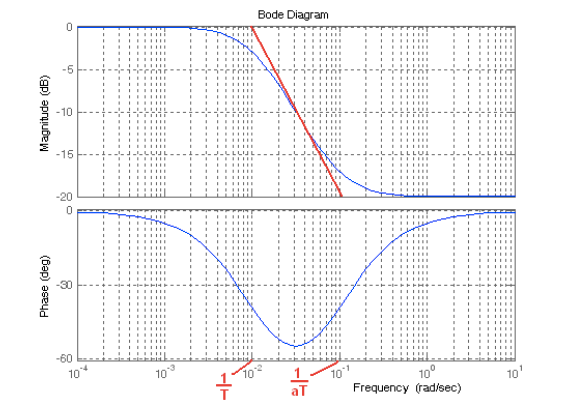

O script a seguir testa diferentes valores de margem de fase desejada (MFd)

MFa=[];ts=[];UP=[];
MFd=linspace(MFg2,MFe,5);
for i=1:length(MFd)
    [c1,a1, T1]=projat(g2,Kc,MFd(i));
    [~,mf]=margin(c1*g2);
    S=stepinfo(feedback(c1*g2,1));
    MFa(i,1)=mf;
    UP(i,1)=S.Overshoot;
    ts(i,1)=S.SettlingTime;
end
Tabela2=table(MFa,UP,ts)
c11=projat(g2,Kc,MFd(3));
c12=projat(g2,Kc,MFd(5));
figure;
bode(Kc*g2,c11*g2,c12*g2);title('Figura 6. Diagrama de Bode')
grid;legend('Kc*g2',num2str(MFd(3)),num2str(MFd(5)))

m1=feedback(c11*g2,1);
m2=feedback(c12*g2,1);
figure
step(m1,m2);title('Figura 7. Resposta ao degrau de dois controladores atraso')
legend(num2str(MFd(3)),num2str(MFd(5)))

3.2 Qual o efeito sobre o gráfico de Bode compensado ao aumentar MFd?

Resposta:

3.3 Qual o efeito sobre a resposta ao degrau ao aumentar MFd?

Resposta:

**Atividade 4: Teste o compensador atraso projetado no motor **

Selecione o compensador que achar mais adequado (I entre 1 e 5) e teste no motor.

I=3; % Escolher um valor da Tabela 2
[c1,a1, T1]=projat(g2,Kc,MFd(I));
seta_saida(obj,U0(1));
[y,u,t] = arduino_lead_lag(obj,Ref,Ts,Tempo, a1, T1, Kc);
seta_saida(obj,0);

figure;
iae=trapz(t,abs(Ref-y));
ss=sprintf('Figura 8. Saída - IAE = %.0f',iae);
subplot(2,1,1);
r=Ref*ones(size(y));
stairs(t,[y 0.98*r 1.02*r]);title(ss);
subplot(2,1,2);
stairs(t,u);title('Controle');

4.1 Verifique o atendimento das especificações (erro, UP, ts, MF)

Resposta:

## Atividade 5 - Projeto do controlador Avanço

O projeto do controlador avanço é mostrado na figura abaixo. Deve-se adicionar fase próximo a frequência em que o módulo cruza 0dB de modo que a margem de fase atual mais a adicionada seja igual à desejada.

5.1 Use o gráfico de Bode de malha aberta de Kc*g2 mostrado na Figura 3 para ver quanta fase deve ser adicionada.

Resposta:

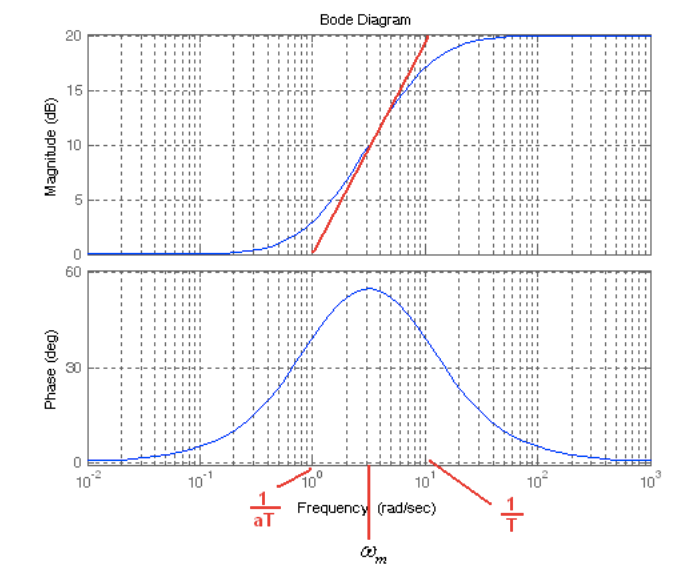

O script a seguir testa diferentes valores de margem de fase adicionada (fi)

MFa=[];ts=[];UP=[];
fi=linspace(5,60,5);
for i=1:length(fi)
    [c2,a2, T2]=projav(g2,Kc,fi(i));
    [~,mf]=margin(c2*g2);
    S=stepinfo(feedback(c2*g2,1));
    MFa(i,1)=mf;
    UP(i,1)=S.Overshoot;
    ts(i,1)=S.SettlingTime;
end
Tabela3=table(MFa,UP,ts)
c21=projav(g2,Kc,fi(3));
c22=projav(g2,Kc,fi(5));
figure;
bode(Kc*g2,c21*g2,c22*g2);title('Figura 9. Gráficos de Bode')
legend('Kc*g2',num2str(MFd(3)),num2str(MFd(5)));grid;
m1=feedback(c21*g2,1);
m2=feedback(c22*g2,1);
figure
step(m1,m2);title('Figura 10. Resposta ao degrau de dois controladores avanço')
legend(num2str(MFd(3)),num2str(MFd(5)));

5.2 Qual o efeito sobre o gráfico de Bode compensado ao aumentar a fase fi?

Resposta:

5.3 Qual o efeito sobre a resposta ao degrau ao aumentar fi?

Resposta:

**Atividade 6: Teste o compensador avanço projetado no motor **

I=0; % escolher I da tabela 3
[c2,a2, T2]=projav(g2,Kc,fi(I));
seta_saida(obj,U0(1));
[y,u,t] = arduino_lead_lag(obj,Ref,Ts,Tempo, a2, T2, Kc);
seta_saida(obj,0);

figure;
iae=trapz(t,abs(Ref-y));
ss=sprintf('Figura 11. Saída - IAE = %.0f',iae);
subplot(2,1,1);
r=Ref*ones(size(y));
stairs(t,y);hold on;plot(t, [0.98*r 1.02*r],'Color','g');title(ss);hold off
subplot(2,1,2);
stairs(t,u);title('Controle');

6.1 Verifique o atendimento das especificações (erro, UP, ts, MF)

Resposta:

**Atividade 7: Projeto do controldor avanco+atraso**

Baseado nos projetos feitos, projete um controlador avanço +atraso para conseguir bom desempenho, testandoo mesmo em simulação

[c1,a1, T1]=projav(g2,Kc,fi(2)); % Escolher fi
[c2,a2, T2]=projat(c1*g2,1,MFd(4)); % Escolher MFd
figure;
margin(c1*c2*g2);title('Figura 12. Gráfico de Bode para controlador avanço-atraso')
grid;


m=feedback(c1*c2*g2,1);
figure;
step(m); title('Figura 13. Resposta ao degrau do controlador avanço + atraso')

7.1 Verifique se conseguiu um desempenho melhor do que o avanço ou atraso sozinhos.